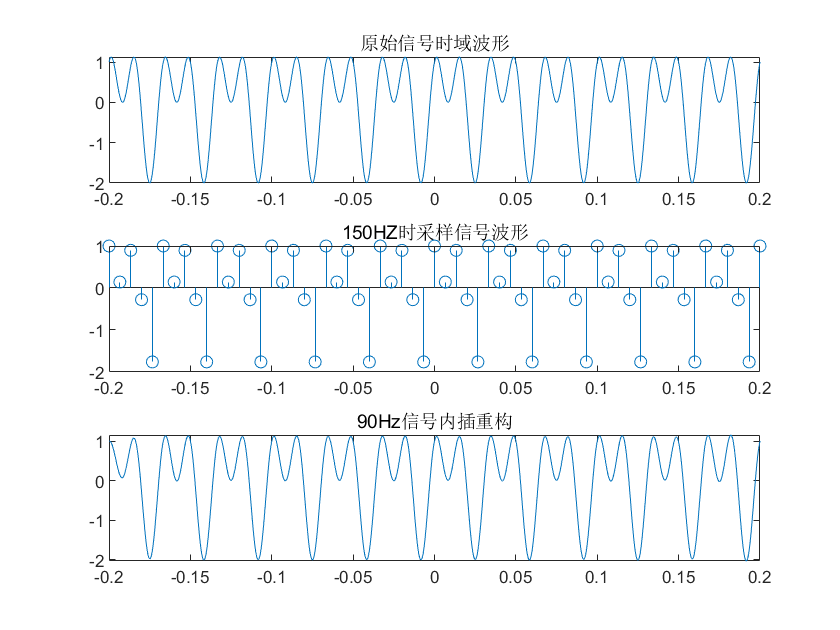

clear all；
% 原始连续信号
dt=0.0005;
t = -0.2 : dt: 0.2;
origin = sin(2 * pi * 30 * t) + cos(2 * pi * 60 * t);   % 原始信号
subplot(3, 1, 1); plot(t, origin), title('原始信号时域波形');
%连续信号采样
f_sampling = 150; % 采样频率

T=1/f_sampling; % 周期
n = floor(-0.2/T ) : floor(0.2/T ); %采样范围 默认间隔 1
t_sampling= n * T;  % n·T
origin_sampling = sin(2 * pi * 30 * t_sampling) + cos(2 * pi * 60 * t_sampling); %采样后的信号
subplot(3, 1, 2);stem(t_sampling, origin_sampling ), title('150HZ时采样信号波形');
%低通滤波器的截止频率为采样频率的1/2
f=sin(2 * pi * 30 * t_sampling) + cos(2 * pi * 60 * t_sampling);
fc=f_sampling/2;
%采样信号恢复
f_covery = f * sinc( f_sampling * ( ones(length(n),1) * t - t_sampling' * ones(1,length(t) ) ));
subplot(3,1,3);plot(t,f_covery);title('90Hz信号内插重构');